# LABORATORIO 4 - CINEMÁTICA DIRECTA

## MÓDELO CINEMÁTICO DIRECTO - PHANTOM X

clear
clc

syms theta1 theta2 theta3 theta4
alpha2=acos(3.39/10.63) %radians

alpha2 = 1.2462


%MTH(ai,alphai,di,thetai,angleType0=rad)
% MTH de O1 respecto a O0
MTH01 = MTHDH(0,90,4.44,theta1,2) %degree and rad 

Unrecognized function or variable 'MTHDH'.

% MTH de O2 respecto a O1
MTH12 = MTHDH(10.63,0,0,theta2+alpha2,2)  %degree and rad 
% MTH de O3 respecto a O2
MTH23 = MTHDH(10.5,0,0,theta3-alpha2,2)%degrees and rad
% MTH de O4 respecto a O3
MTH34 = MTHDH(12.8,0,0,theta4,2) %degree and rad

Matriz de transformación homogénea desde la base hasta el efector fina

%MTH de O5 respecto a O0.
MTH04=MTH01*MTH12*MTH23*MTH34

### Gráfica del modelo con el Toolbox de PeterCorke:

clear
clc
d = [9.7, 0, 0, 0];
a = [0, 10.67, 10.135, 0]

a =          0   10.6700   10.1350         0


b1 = deg2rad(71.138)

b1 = 1.2416

q =      0     0     0     0


 
robot_phantomX = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


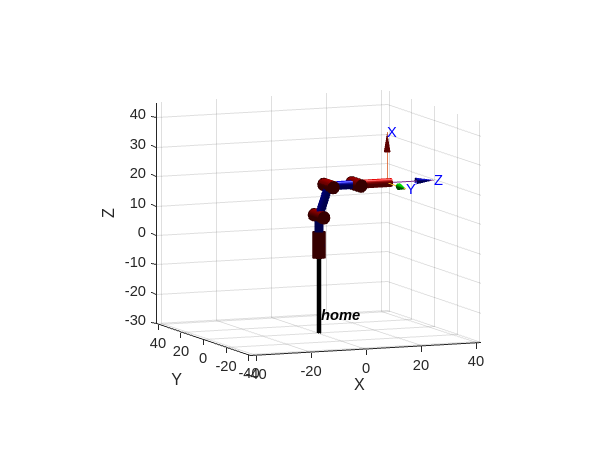

q =     0.4363    0.4363    0.3491   -0.3491


 
robot_phantomX = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


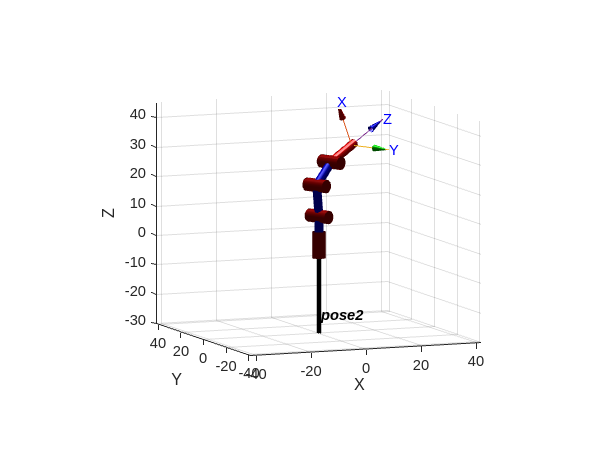

q =    -0.6109    0.6109   -0.5236    0.5236


 
robot_phantomX = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


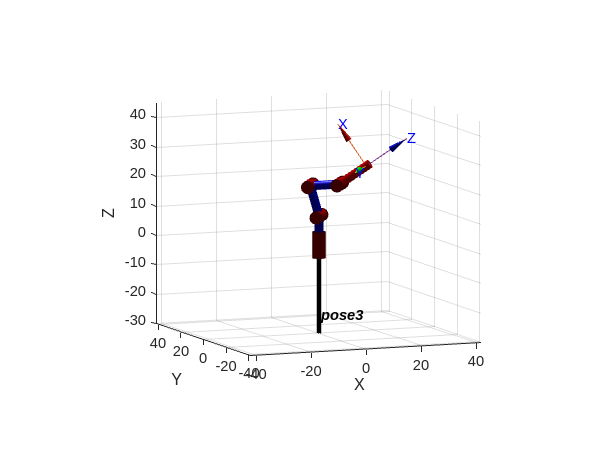

q =     1.4835   -0.3491    0.9599    0.4363


 
robot_phantomX = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


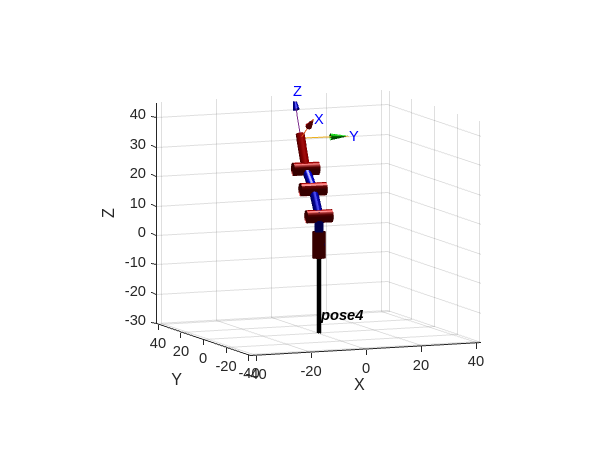

q =     1.3963   -0.6109    0.9599   -0.7854


 
robot_phantomX = 
 
noname:: 4 axis, RRRR, stdDH, fastRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


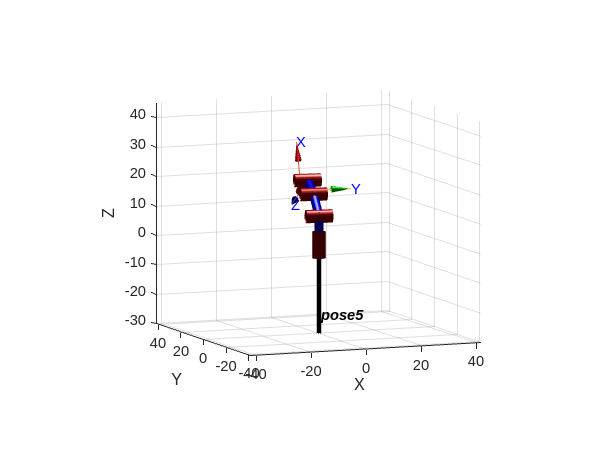

offset = [0, b1, -b1, pi/2];

q1 = [0, 0, 0, 0];
q2 = [25, 25, 20, -20];
q3 = [-35, 35, -30, 30];
q4 = [85, -20, 55, 25];
q5 = [80, -35, 55, -45];
poses = [q1; q2; q3; q4; q5];

names = ["home", "pose2", "pose3", "pose4", "pose5"];

for i = 1:length(poses)

    q = poses(i, :)*pi/180

    % Orden parametros funcion link [THETA D A ALPHA SIGMA(0R,1P) OFFSET]
    DHparameters = [q(1) d(1) a(1) pi/2 0 offset(1);
                    q(2) d(2) a(2) 0    0 offset(2);
                    q(3) d(3) a(3) 0    0 offset(3);
                    q(4) d(4) a(4) pi/2 0 offset(4)];
    L(1) = Link(DHparameters(1,:));
    L(2) = Link(DHparameters(2,:));
    L(3) = Link(DHparameters(3,:));
    L(4) = Link(DHparameters(4,:));
    robot_phantomX = SerialLink(L);
    robot_phantomX.tool = trotx(0) * transl(0, 0, 11.19)
    robot_phantomX.name = names(i);
    figure()
    robot_phantomX.plot(q);
    view([-22.3 7.9])
    zlim([-30 45])
end


function [H] = MTH(thetai,di,ai,alphai,angleType)
 %Función para calcular la Matriz de Transformación Homogénea a partir de los parámetros DHstd 
    if angleType == 0 %rad
        H = [cos(thetai), -sin(thetai)*cos(alphai), sin(thetai)*sin(alphai), ai*cos(thetai);sin(thetai), cos(thetai)*cos(alphai), -cos(thetai)*sin(alphai), ai*sin(thetai); 0, sin(alphai), cos(alphai), di; 0, 0, 0, 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai), -sind(thetai)*cosd(alphai), sind(thetai)*sind(alphai), ai*cosd(thetai);sind(thetai), cosd(thetai)*cosd(alphai), -cosd(thetai)*sind(alphai), ai*sind(thetai); 0, sind(alphai), cosd(alphai), di; 0, 0, 0, 1];
    elseif angleType == 2 %thetai en rad, alphai en degree
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %thetai en degree, alphai en rad
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end

function [H] = MTH3(thetai,di,ai,alphai,angleType)
 %Función para calcular la Matriz de Transformación Homogénea a partir de los parámetros DHstd 
    if angleType == 0 %rad
        H = trotz(thetai)*transl(0,0,di)*transl(ai,0,0)*trotx(alphai);
    elseif angleType == 1 %degrees
        H = trotz(thetai, "deg")*transl(0,0,di)*transl(ai,0,0)*trotx(alphai,"deg");
    elseif angleType == 2 %thetai en rad, alphai en degree
        H = simplify(trotz(thetai)*transl(0,0,di)*transl(ai,0,0)*trotx(alphai,"deg"));
    end
end